clear; clear path; clc;
cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;
format shortG

Ps;
% P = 1000;
% I = 10000;
% D = 40;
% N = 100;


First we try only P

P = 10;
I = 0;
D = 0;
N = 1;
Cs = pidGen(P,I,D,N,1);
controlledDist = Ps/(1+Cs*Ps);
% bodeCompare(Ps,Cs)

we see that the P will never stabilize the system, as shown by the root locus. Now we add a D term, to see if this can remove the marginal stability. We can tell that we need to change the system phase

P = 0;
I = 0;
D = 40;
N = 100;
Cs = pidGen(P,I,D,N,1);
controlledDist = Ps/(1+Cs*Ps);
% bodeCompare(Ps,Cs)

We see that with a D controller we will always be adding 90deg phase to the zero frequency. This poses a problem, as this is precisely not what we want. By increasing the N term we can change the bandwidth of the controller (higher bandwidth means phase addition startd to reduce at higher frequencies). and with the D term we can increase the gain that is added. However, with just a D controller we weill never be able to add the right amount phase to the steady state system (0-frequency).

Hence We will now try a PD controller.

P = 1000;
I = 0;
D = 400;
N = 1;
Cs = pidGen(P,I,D,N,1);
controlledDist = Ps/(1+Cs*Ps);
% bodeCompare(Ps,Cs)

With a PD controller we see we can actually add phase to a band. This is nice. Because of this we see We now have stabilising controller. The Gain in Ls is negative beyond the phase crossover frequency, which means that high frequencies, like residual oscilations are filtered out.

With The P term we can change the width of the phase band peak and the higher of the gain added to higher frequencies, bot not the frequencies themselves. The Dterms, does the same, but in different effects. Higher D means **more** added gain and **wider** peak. higher P means **less **added gain and **narrower** peak. With these two factors combined we can excatly shape the phase band and the gain gradient as we please.

With the n term we can **place the gain addition and phase band**

**But we still have steady state error, so we need to work on the low frequency range**

P = 1000;
I = 0;
D = 40;
N = 100;
Cs = pidGen(P,I,D,N,1);
controlledDist = Ps/(1+Cs*Ps);
% bodeCompare(Ps,Cs)
% stepinfo(Ps/(1+Ps*Cs))

We wil now always be subtracting 90deg phase from the zero fequency, which yields a phase of -270 there. this is desirable.  We will then again try to find a PD controller that stabilises the system while keeping the  I term off.

With a phase band around the 1300 rad/s that is made somewhat narrow we can lift the plant phase up such that it has some frequency range where it has positive phase. meanwhile we also start adding roughly 75dB to frequencies over this threshold and 60dB below this thrershold. As a result of L(s) has a positive, relatively large magnitude for low frequencies and a low magnitude for high frequencies. As a result of this high frequency-band responses will not hav a large effect, while low frequency content, such as a constant disturbance will be acted on.

The notch exisitng in the plant is also pulled down by this controller to the negative dB range. This means this resonance frequency is also not a problem anymore. The gain crossover happens at a lower frequency than the phase crossover. This is a requirement for stability, as we don't want negative phase to be amplified.

However, we still see a steady state error. In order to do this we will now introduce the integrator, to see if we can remove this.

P = 1000;
I = 10000;
D = 40;
N = 100;
Cs = pidGen(P,I,D,N,1);
controlledDist = Ps/(1+Cs*Ps);
% bodeCompare(Ps,Cs)
% stepinfo(Ps/(1+Ps*Cs))

with an I of 1 we see that the steady state error is removed, but the position of the phase band and the shape of the gain is quite messed up

We see now that the controlled system converges much faster with an I of 100, but still we get a step response that is undesirable. We can see this in the bode plot as the phase for the lower fequencies not crossing the 180 degrees line fast enough. We will hence continue to increase the integrator gain.

With an I of 10000 we see a very nice step response. A good amount of gain is added to the lower frequencies, and the notch is still in the negative decibels. we also have a nice zero phase. as -270. We see a gain steepness dropoff in the gain just at the phase crossover. This is already at a very low magnitude, meaning that there is little room between the crossover frequencies. Because of this the system will not be very robust against perturbations; not something we want in an HDD. However, is we move the phase crossover left, we will likely suffer speed performance of the system.

**BELOW: Yes, indeed.**

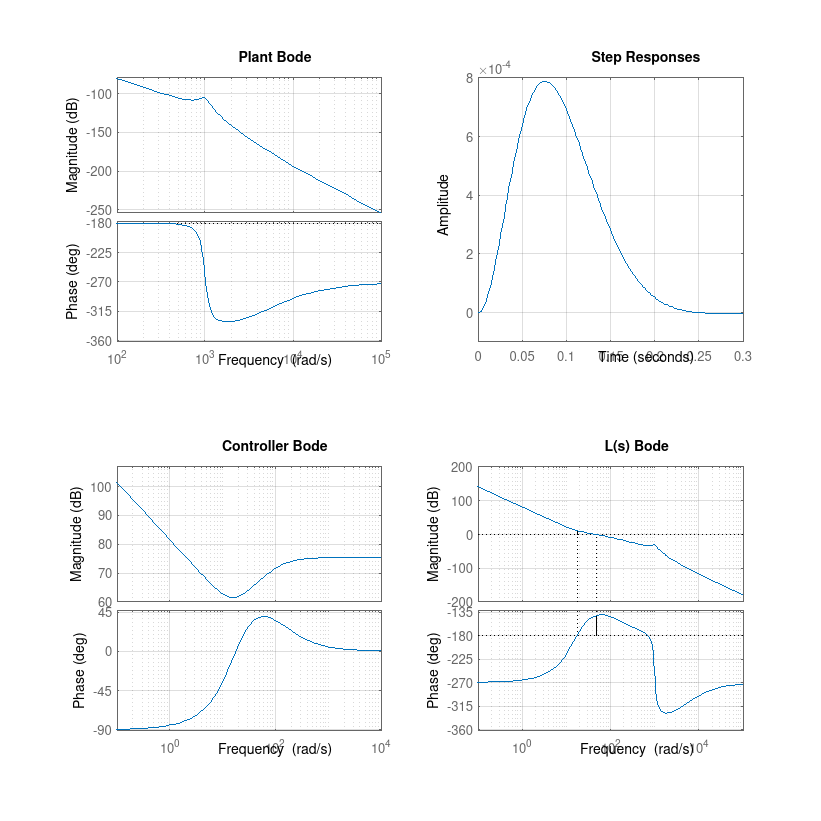

P = 1100;
I = 12000;
D = 40;
N = 120;
Cs = pidGen(P,I,D,N,1);
controlledDist = Ps/(1+Cs*Ps);
bodeCompare(Ps,Cs)

% stepinfo(Ps/(1+Ps*Cs))

We see that with increasing the integrator and adding more gain we can perhaps speed up the system slightly.

If done properly perhaps the D and N terms could also be tuned along with the P and I terms to make a faster response without letting the effect of the step disturbance grow or having a to large undershoot .

It is not trivial to shape the bode of the controller exactly as one wants for a pid controller. Hence going further into this will be a matter of optimisation through trial and error, which is what we want to avoid.

Therefore we conclude the pid controller as the above.

function [] = bodeCompare(Tf1,Tf2)
    fig = figure('Position',[0 0 1000 1000]);clf; hold on;  
        subplot(2,2,1)
            margin(Tf1);grid on;
            title('Plant Bode')
        subplot(2,2,2)
            % step(Tf1/(1+Tf1)); hold on;
           step(Tf1/(1+Tf1*Tf2));grid on;
           title('Step Responses')
           % axis([0 25 -1 9])
        subplot(2,2,3)
            margin(Tf2);grid on;
            title('Controller Bode')
        subplot(2,2,4)
            margin(Tf1*Tf2); grid on;
            title('L(s) Bode')
end